# **电磁超表面的远场方向图演示（利用实时脚本等解析计算） **

**        人工电磁表面（简称超表面）具有超薄的厚度，在平面内使用“人工原子”按照一定规律排列。根据惠更斯原理，在外加电磁场的作用下，人工原子作为次波源，像单元天线一样向四周辐射，且可实现受控的电磁辐射强度和相位分布，从而完成灵活地对电磁波波前调控，对外呈现特异的电磁特性，如反常的折射定律等，具有广阔的研究和应用前景。现结合相控阵的理论对其中的一些电磁现象进行分析。**

**        假设电磁波以角度**$$$\theta_{i}$$$**入射到超表面。此时，各个小天线被激励向四周做二次辐射。其中辐射到上半空间的电磁波就是反射电磁波。上述分析实际上就是惠更斯原理的典型应用。因此，可以把超表面当作平面天线阵来分析。与真正有源天线阵不同，超表面对应的天线阵是无源的，且对于天线阵中各个天线相位的控制，不是通过馈电网络来实现，而是通过波程差和各个单元的反射相位差来决定。对于下图(b)中的天线来讲，相邻天线之间由“馈电”造成的相位差就包含了下图(a)所示的波程差**$$$k_{0}n_{i}\sin\theta_{i}dx$$$**，以及相邻单元的反射相位差，记为**$$$d\phi $$$**。因此,沿着图中所示方向，右侧天线比左侧天线的“馈电”从相位上滞后了**$$$\xi=k_{0}n_{\mathrm{i}}\sin\theta_{\mathrm{i}}\mathrm{d}x-\mathrm{d}\phi $$$**表示的数量。**

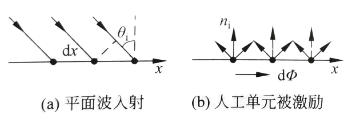

**        假设反射电磁波沿出射方向有最大辐射，则由图中可以看出，右侧天线辐射的电磁波比左侧天线要超前**$$$k_{0}n_{i}\sin\theta_{r}dx$$$**。根据天线阵中阵因子的计算结论可知，在最大辐射方向，各个单元天线总的相位差为零，即各个子波源同相位到达，从而实现同相叠加，即**


$$$$k_{0}n_{i}sin\theta_{i}dx-d\phi=k_{0}n_{i}sin\theta_{r}dx$$$$


**此式经过整理，就是前面所描述的广义反射定律的公式，即**


$$$$k_0n_i\sin\theta_i-k_0n_i\sin\theta_r=\frac{\mathrm{d}\phi}{\mathrm{d}x}$$$$


**        同样的道理，当均匀平面波入射到电磁超表面时，向下半空间辐射的电磁波就可以看作透射波。利用相似的分析过程，可以得到**


$$$$k_0n_i\sin\theta_i-k_0n_t\sin\theta_t=\frac{\mathrm{d}\phi}{\mathrm{d}x}$$$$


**这就是广义的折射定律。**

**        通过对“人工原子”的几何结构如尺寸 w 进行调控，可以对反射电磁波的幅度、相位等进行操控（反射型主要是相位），从而实现对反射电磁波的灵活控制。典型情况下，可以设置一种“人工原子”的反射相位为0，而另外一种单元结构的反射相位为π。对这两种单元结构进行适当的排列，即可实现特定功能。**

## **一、电磁超表面均匀平面天线阵（排布方式一）**

**        如下图所示，各个单元结构或者小天线只沿z方向周期排布，相位差为**$$$\pm\pi $$$**，这实际上是一个一维情况。则可以断定，在垂直于表面的远处，各个单元（元天线）的辐射幅度相同，但是相位差为**$$$\pi $$$**，所以无反射场；或者说，反射的最大方向一定不在平面法方向。**

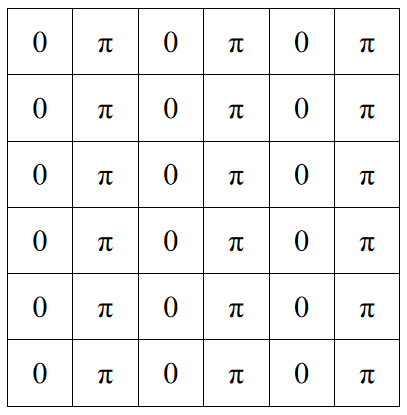

**        确定最大的反射方向，就可以用线性天线阵的理论。假设最大反射方向与 xoy 平面的夹角为**$$$\varphi$$$**，则根据均匀直线式天线阵理论，有**


$$$$kd\cos\varphi=\xi $$$$


**        这里，**$$$\xi=\pm\pi $$$**，假设**$$$d=\lambda $$$**，代人上式，则**$$$\varphi=\pm\frac\pi3$$$**。换句话说，当电磁波从垂直方向入射时，反射波束有两个，它们与 xoy 平面的夹角为**$$$\varphi=\pm\frac\pi3$$$**。这个现象说明：电磁波入射到电磁超表面时，发生了反常反射，入射角为 0，但是反射角为**$$$\pm\frac{\pi}{6}$$$**。**

- **定义参数**

freq=1e+9;                              %工作频率
omega=2*pi*freq;
c=3e8;                                  %光速
lambda=c/freq;                          %波长
k=2*pi/lambda;                          %波数
m=6;
n=6;                                    %反射面的尺寸
reflect_phi=repmat([1 0],m,n/2);        %相位矩阵
reflect_amp=ones(size(reflect_phi));    %幅度矩阵
reflect_phi=reflect_phi.*pi;            %相位矩阵
d=lambda;                               %单元间距
M=500;
N=500;                                  %方位角离散化的个数
theta=linspace(0,pi/2,M);
phi=linspace(0,pi*2,N);                 %theta方向M份，phi方向N份
[THETA,PHI]=meshgrid(theta,phi);        %构造网格
E_total=zeros(M,N);                     %初始电场强度，各方向均为0

- **使用叠加原理计算远场方向图**

**        使用叠加原理计算由于波程差造成的相位差别，可使用“surf”函数绘制远场方向图，用“contourf”绘制二维远场方向图。**

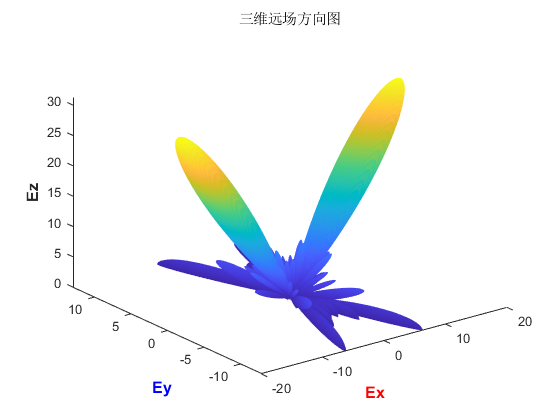

for ii=1:1:m                           %循环m×n次，叠加原理计算远场
    for jj=1:1:n
        E_total=E_total+reflect_amp(ii,jj).*exp(1i.*(reflect_phi(ii,jj)+k.*d.*((jj-1/2).*cos(PHI)+(ii-1/2).*sin(PHI)).*sin(THETA)));                                 
    end
end
Ex=abs(E_total).*sin(THETA).*cos(PHI);
Ey=abs(E_total).*sin(THETA).*sin(PHI);
Ez=abs(E_total).*cos(THETA);            %电场的三个分量
Exx=sin(THETA).*cos(PHI);
Eyy=sin(THETA).*sin(PHI);               %将方位角转换为直角坐标
Ezz=abs(E_total);                       %方位角上对应的电场模值
figure
surf(Ex,Ey,Ez,'EdgeColor','none');
xlabel('Ex','FontSize',12,'FontWeight','b','Color','r');
ylabel('Ey','FontSize',12,'FontWeight','b','Color','b');
zlabel('Ez','FontSize',12,'FontWeight','b');
title('三维远场方向图')
grid off;   
set(gcf,'Visible','on');   	    %强制图片弹出显示

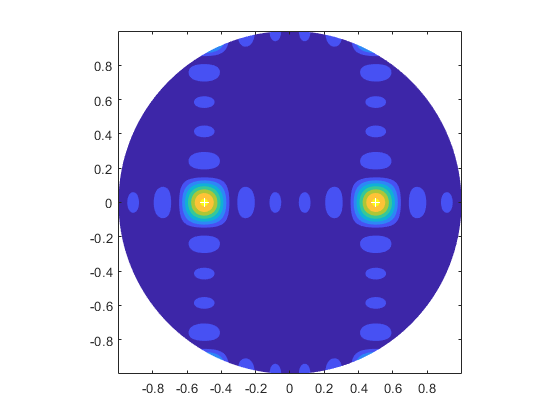

figure
contourf(Exx,Eyy,Ezz,'LineStyle','none');              	%绘制等高线并填充
hold on;
theta0=pi/6;phi0=[0 pi];                            	
x0=sin(theta0)*cos(phi0);
y0=sin(theta0)*sin(phi0);
plot(x0,y0,'w+');                                 	%绘制解析结果以验证
axis equal
set(gcf,'Visible','on');   	    %强制图片弹出显示

## **二、电磁超表面均匀平面天线阵（排布方式二）**

**        如下图所示，如果各个单元结构或者小天线沿 **$$$x,y$$$**方向周期排布，相位差**$$$\pm\pi $$$**，则各个单元结构组成了一个均匀平面天线阵。**

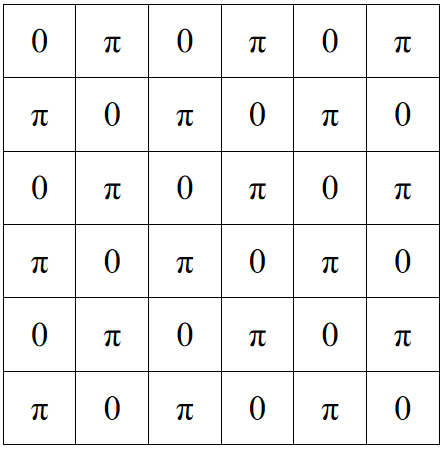

**        确定最大的反射方向，就可以用平天线阵的理论，有**


$$$$kd\sin\theta\cos\varphi=\xi_{x}=\pm\pi,\quad kd\sin\theta\sin\varphi=\xi_{y}=\pm\pi $$$$


**        假设各个单元之间的间距依旧为工作波长，则可以求得**

$$$\theta_{m}=\frac{\pi}{4},\quad\varphi_{m}=\pm\frac{\pi}{4}$$$**  或   **$$$\varphi_{\mathrm{m}}=\pm\frac{3\pi}4$$$  	

**可以看到，这种情况下，反射波束有四个，分布在**$$$\theta=\frac\pi4$$$**的圆锥面上。**

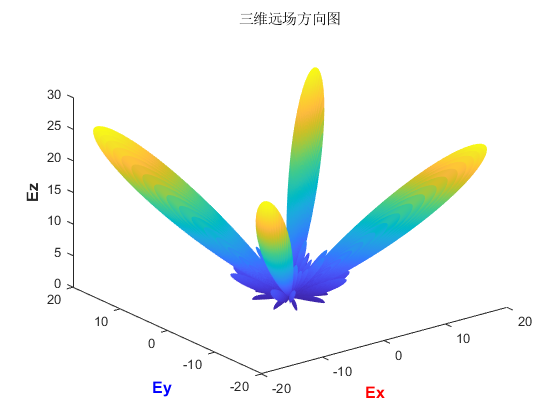

freq=1e+9;                                      	%工作频率
omega=2*pi*freq;
c=3e8;                                         	%光速
lambda=c/freq;                                  	%波长
k=2*pi/lambda;                                  	%波数
m=6;n=6;                                      	%反射面的尺寸
reflect_phi=repmat(eye(2,2),m/2,n/2);              	
reflect_amp=ones(size(reflect_phi));                 	%幅度矩阵
reflect_phi=reflect_phi.*pi;                        	%相位矩阵
d=lambda;                                      	%单元间距
M=500;N=500;                                  	%方位角离散化的个数
theta=linspace(0,pi/2,M);phi=linspace(0,pi*2,N);       	%theta方向M份；phi方向N份
[THETA,PHI]=meshgrid(theta,phi);                  	%构造网格
E_total=zeros(M,N);                            		%初始电场强度，各方向均为0
for ii=1:1:m                                     	%循环m*n次，叠加原理计算远场
for jj=1:1:n
E_total=E_total+reflect_amp(ii,jj).*exp(1i.*(reflect_phi(ii,jj)+k.*d.*((jj-1/2).*cos(PHI)+(ii-1/2).*sin(PHI)).*sin(THETA)));         %叠加原理，式（9-5a），位置从单元中心计算
end
end
Ex=abs(E_total).*sin(THETA).*cos(PHI);
Ey=abs(E_total).*sin(THETA).*sin(PHI);
Ez=abs(E_total).*cos(THETA);                     	%电场三个分量
Exx=sin(THETA).*cos(PHI);Eyy=sin(THETA).*sin(PHI); %将方位角转换为直角坐标
Ezz=abs(E_total);                                 	%方位角上对应的电场模值
figure
surf(Ex,Ey,Ez,'EdgeColor','none');
xlabel('Ex','FontSize',12,'FontWeight','b','Color','r');
ylabel('Ey','FontSize',12,'FontWeight','b','Color','b');
zlabel('Ez','FontSize',12,'FontWeight','b');
title('三维远场方向图')
grid off;
set(gcf,'Visible','on');   	    %强制图片弹出显示

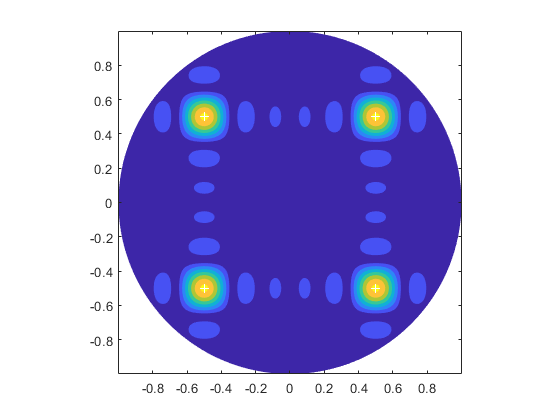

figure
contourf(Exx,Eyy,Ezz,'LineStyle','none');              	%绘制等高线并填充
hold on;
theta0=pi/4;phi0=[pi/4:pi/2:7*pi/4];                	
x0=sin(theta0)*cos(phi0);
y0=sin(theta0)*sin(phi0);
plot(x0,y0,'w+');                                 	%绘制解析结果以验证
axis equal
set(gcf,'Visible','on');   	    %强制图片弹出显示